%Lab 2

R1.a)

M=512;
n=0:(M-1);
w0=4.6*2*pi/M;

x=5*cos(w0*n+1)+2*cos(2*w0*n+2)+3*cos(5*w0*n+3);

R1.b)

We can observe a periodic signal, made of cosines. Additionally we can see that we have a max amplitude of almost 10 and a min amplitude of about -7

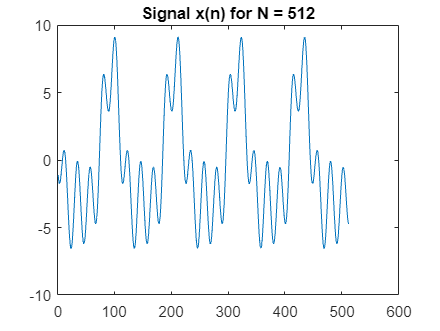

plot(x);
title('Signal x(n) for N = 512');

R1.c)

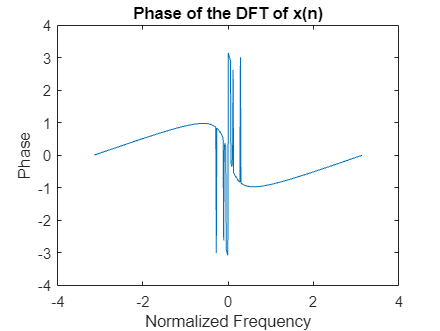

x_FT=fft(x,512); 
delta_Freq=2*pi/(length(x_FT)-1);
f=-pi:delta_Freq:pi;

x_phase=angle(x_FT);

x_abs = abs(x_FT);


% Phase plot

plot(f,fftshift(x_phase));
ylabel('Phase')
xlabel('Normalized Frequency')
title('Phase of the DFT of x(n)')

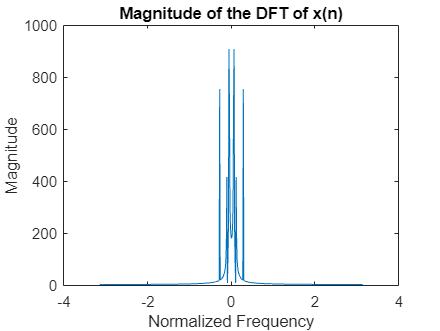


%Missing Comemnt about the phase

% Magnitude plot
plot(f,fftshift(x_abs));
ylabel('Magnitude')
xlabel('Normalized Frequency')
title('Magnitude of the DFT of x(n)')


%There are predominant low (close to 10) 
%and high (close to 500) frequencies in x(n) 

R1.d)

%3 largest peaks of the magnitude
[peaks,index] = maxk(x_abs, 3);
peaks

peaks =   908.6356  908.6356  754.1891


peaks_phase = x_phase(index)

peaks_phase =    -0.2767    0.2767    3.0157


f(index)

ans =    -3.0801    3.0924   -2.8588


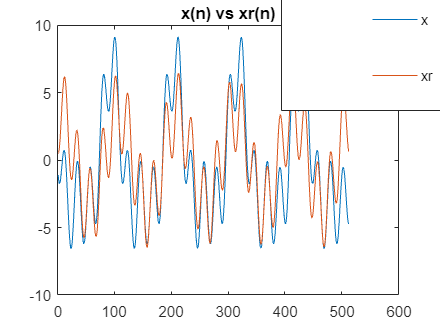

%the frequency is given by the index of the peaks

rec_x = zeros(size(x));
rec_x(index) = x_FT(index);
rec_x(512-index+2) = conj(x_FT(index));
xr = ifft(rec_x,512);

plot(x,'DisplayName','x');
hold on
plot(xr,'DisplayName','xr');
title('x(n) vs xr(n)');
hold off

legend("Position", [0.72226,0.72433,0.38557,0.26275]);

R1.e)

We can see that the signals look somewhat a like, however

there are some clear differences. 

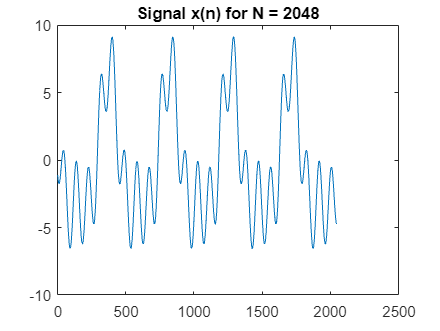

%R1.a and R1.b
M=2048;
n=0:(M-1);
w0=4.6*2*pi/M;
x2=5*cos(w0*n+1)+2*cos(2*w0*n+2)+3*cos(5*w0*n+3);
plot(x2);
title('Signal x(n) for N = 2048');

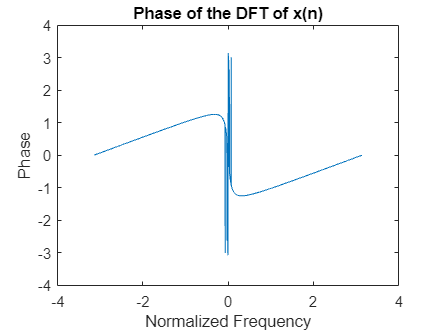


%R1.c
x_FT=fft(x2,2048);
delta_Freq=2*pi/(length(x_FT)-1);
f=-pi:delta_Freq:pi;

x_phase=angle(x_FT);
x_abs = abs(x_FT);
% Phase plot
plot(f,fftshift(x_phase));
ylabel('Phase')
xlabel('Normalized Frequency')
title('Phase of the DFT of x(n)')

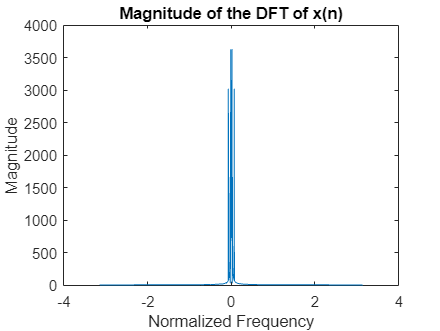

%Missing comment 
% Magnitude plot
plot(f,fftshift(x_abs));
ylabel('Magnitude')
xlabel('Normalized Frequency')
title('Magnitude of the DFT of x(n)')

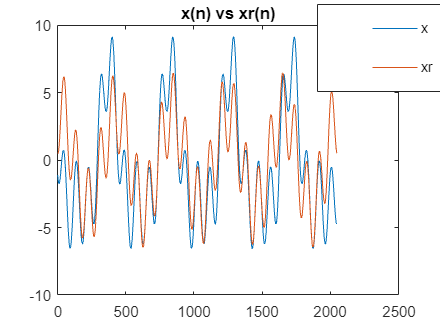


%R1.d
%3 largest peaks of the magnitude
[peaks,index] = maxk(x_abs, 3);
peaks_phase = x_phase(index);
%the frequency is given by the index of the peaks
rec_x = zeros(size(x2));
rec_x(index) = x_FT(index);
rec_x(2048-index+2) = conj(x_FT(index));
xr = ifft(rec_x,2048);

%R1.e
plot(x2,'DisplayName','x');
hold on
plot(xr,'DisplayName','xr');
title('x(n) vs xr(n)');
hold off

legend("Position", [0.72226,0.72433,0.38557,0.26275]);

R1.f) The DFT length increase improves frequency resolution, however the three peaks in the magnitude spectrum were already well defined and as such they are not affected by this improvement in frequency resolution, as such there was no difference between the reconstructed signals.  

[Audio, fs] = audioread("Lab2\how_many_roads.wav");
AudioX = transpose(Audio(:,1));
soundsc(AudioX, fs);

R2.a)

M=2048;
StartSeg = 48500;
voiceSegment = AudioX(StartSeg:StartSeg+M);

R2.b)

voice_S_FFT = fft(voiceSegment,M);
[voice_peaks,voice_index] = maxk(abs(voice_S_FFT), 3);

%the frequency is given by the index of the peaks
rec_voice = zeros(size(voiceSegment));
rec_voice(voice_index) = voice_S_FFT(voice_index);
rec_voice(M-voice_index+2) = conj(voice_S_FFT(voice_index));

voice_r = ifft(rec_voice,M);

R2.c)

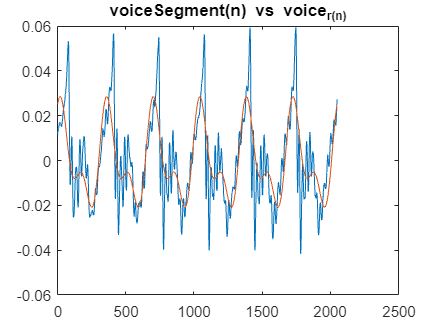

plot(voiceSegment,'DisplayName','x');
hold on
plot(voice_r,'DisplayName','xr');
title('voiceSegment(n) vs voice_r(n)');
hold off

R2.d)

The reconstructed signal isn't very accurate, but does folow the general wave of the original signal. As a voice is a very complex signal, the 3 most important sinusoids are not enogh to accuratly represent the voice signal.

clear sound; 
%S_min = threshold
threshold = 8;
voice_FFT = fft(AudioX);
r_index = find(abs(voice_FFT) <= threshold)

r_index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    32    36    53    58    60    62    79    80    83    84    86    88    90    92    93    94    97   100   101   102   104   107   108   111   112   114   115   116   117   118   121   122


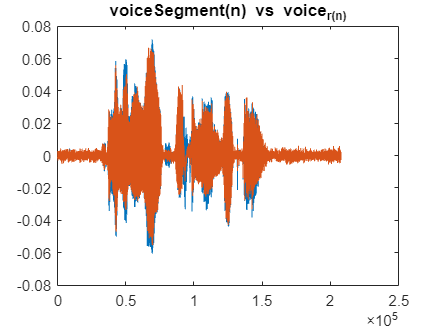

    
rec_audioX = voice_FFT;
rec_audioX(r_index) = 0;

audio_r = ifft(rec_audioX);

plot(AudioX,'DisplayName','x');
hold on
plot(audio_r,'DisplayName','xr');
title('voiceSegment(n) vs voice_r(n)');
hold off


soundsc(AudioX,fs)
soundsc(audio_r,fs)

R2.e)

About 201435 coefiecient where discarded.